Max Climb Rate: 3194.44 ft/min


Avg Cruise Speed: 444.72 kts


Descent Duration: 44.00 min


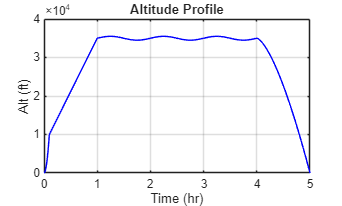

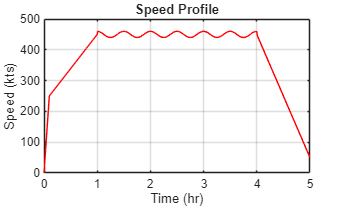

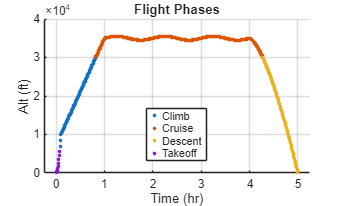

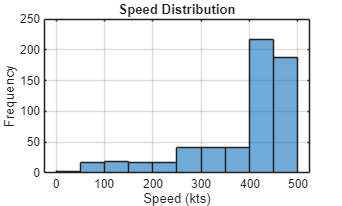

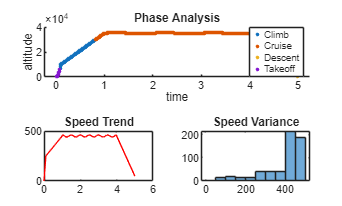

%Engineering Computer Applications Final Project
%Benjamin Oakes, Dakota D'Angelo, & Christopher Bourjaili


clear; % Clears all variables from workspace
clc; % Clears command window text
close all; % Closes all open figure windows

t_hours = (0:30/3600:5)';  % Creates time vector from 0 to 5 hours in 30-second increments

altitude_ft = zeros(size(t_hours)); % Preallocates altitude array
speed_kts = zeros(size(t_hours));   % Preallocates speed array

t_takeoff_end = 0.1;  % Defines end time of takeoff phase
t_climb_end = 1.0;    % Defines end time of climb phase
t_cruise_end = 4.0;   % Defines end time of cruise phase
t_descent_end = 5.0;  % Defines end time of descent phase

idx_takeoff = t_hours <= t_takeoff_end; % Logical index for takeoff phase
altitude_ft(idx_takeoff) = 10000 * (t_hours(idx_takeoff) / t_takeoff_end).^2; % Quadratic altitude increase during takeoff
speed_kts(idx_takeoff) = 250 * (t_hours(idx_takeoff) / t_takeoff_end); % Linear speed increase during takeoff

idx_climb = (t_hours > t_takeoff_end) & (t_hours <= t_climb_end); % Logical index for climb phase
t_climb_segment = t_hours(idx_climb) - t_takeoff_end; % Time elapsed in climb phase
climb_duration = t_climb_end - t_takeoff_end; % Total climb duration

altitude_ft(idx_climb) = altitude_ft(find(idx_takeoff,1,'last')) + ... % Start from end of takeoff altitude
    (35000 - altitude_ft(find(idx_takeoff,1,'last'))) * (t_climb_segment / climb_duration); % Linear interpolation to cruise altitude

speed_kts(idx_climb) = 250 + (450 - 250) * (t_climb_segment / climb_duration); % Linear speed increase during climb

idx_cruise = (t_hours > t_climb_end) & (t_hours <= t_cruise_end); % Logical index for cruise phase
altitude_ft(idx_cruise) = 35000 + 500 * sin(2 * pi * (t_hours(idx_cruise) - t_climb_end)); % Small sinusoidal altitude variation during cruise
speed_kts(idx_cruise) = 450 + 10 * cos(4 * pi * (t_hours(idx_cruise) - t_climb_end)); % Small oscillations in cruise speed

idx_descent = (t_hours > t_cruise_end) & (t_hours <= t_descent_end); % Logical index for descent phase
t_descent_segment = t_hours(idx_descent) - t_cruise_end; % Time elapsed in descent phase
descent_duration = t_descent_end - t_cruise_end; % Total descent duration

altitude_ft(idx_descent) = 35000 * (1 - (t_descent_segment / descent_duration).^1.5); % Nonlinear descent curve
speed_kts(idx_descent) = 450 - (450 - 50) * (t_descent_segment / descent_duration); % Linear deceleration during descent

flightDataTable = table(t_hours, altitude_ft, speed_kts, 'VariableNames', {'Time_hr', 'Altitude_ft', 'Speed_kts'}); % Create data table
writetable(flightDataTable, 'flight_data.csv'); % Write table to CSV file

data = readtable('flight_data.csv'); % Read CSV file into MATLAB
time = data.Time_hr; % Extract time column
altitude = data.Altitude_ft; % Extract altitude column
speed = data.Speed_kts; % Extract speed column

CRUISE_ALT_THRESHOLD = 30000; % Defines altitude threshold for cruise classification

alt_rate = [0; diff(altitude) ./ diff(time)]; % ft/hr % Computes rate of altitude change
phases = strings(length(time), 1); % Initializes string array for phase labels

for i = 1:length(time) % Loops through each time step
    if altitude(i) > CRUISE_ALT_THRESHOLD % Checks if aircraft is above cruise altitude
        phases(i) = "Cruise"; % Assign cruise phase
    elseif alt_rate(i) > 500 % Checks for strong upward climb rate
        if speed(i) < 200 % Checks for low speed during climb
            phases(i) = "Takeoff"; % Assign takeoff phase
        else
            phases(i) = "Climb"; % Assign climb phase
        end
    elseif alt_rate(i) < -500 % Checks for strong descent rate
        phases(i) = "Descent"; % Assign descent phase
    else % Otherwise ambiguous flight condition
        if altitude(i) < 1000 % Near ground level check
            phases(i) = "Takeoff"; % Assign takeoff phase
        else
            phases(i) = "Cruise"; % Default to cruise phase
        end
    end
end

phases = categorical(phases); % Converts phase labels to categorical type

max_climb_rate = max(alt_rate(phases == "Climb")) / 60; % Computes max climb rate in ft/min

avg_cruise_speed = mean(speed(phases == "Cruise")); % Computes average cruise speed

descent_duration_min = sum(phases == "Descent") * (time(2) - time(1)) * 60; % Computes descent duration in minutes

fprintf('Max Climb Rate: %.2f ft/min\n', max_climb_rate); % Prints max climb rate
fprintf('Avg Cruise Speed: %.2f kts\n', avg_cruise_speed); % Prints average cruise speed
fprintf('Descent Duration: %.2f min\n', descent_duration_min); % Prints descent duration

figure; plot(time, altitude, 'b'); title('Altitude Profile'); xlabel('Time (hr)'); ylabel('Alt (ft)'); grid on; % Plots altitude over time
figure; plot(time, speed, 'r'); title('Speed Profile'); xlabel('Time (hr)'); ylabel('Speed (kts)'); grid on; % Plots speed over time
figure; gscatter(time, altitude, phases); title('Flight Phases'); xlabel('Time (hr)'); ylabel('Alt (ft)'); grid on; % Plots altitude colored by phase
figure; histogram(speed); title('Speed Distribution'); xlabel('Speed (kts)'); ylabel('Frequency'); grid on; % Plots speed distribution histogram

figure('Name', 'Dashboard'); % Creates dashboard figure
tiledlayout(2,2); % Creates 2x2 layout

nexttile([1 2]); gscatter(time, altitude, phases); title('Phase Analysis'); % Top wide plot
nexttile; plot(time, speed, 'r'); title('Speed Trend'); % Bottom-left plot
nexttile; histogram(speed); title('Speed Variance'); % Bottom-right plot
